# INPUT

[audio_data, Fs] = audioread("test_audio_file.wav");
% [noise_data, Fs2] = audioread("test_noise_file.wav");

## Parameters before Filtering

len_time = length(audio_data) / Fs

len_time = 4

data_range = length(audio_data);
time =linspace(0,len_time,data_range);

## Audio player (Original)

sound(audio_data, Fs, 8);

## Plot for amplitude vs Time (Original)

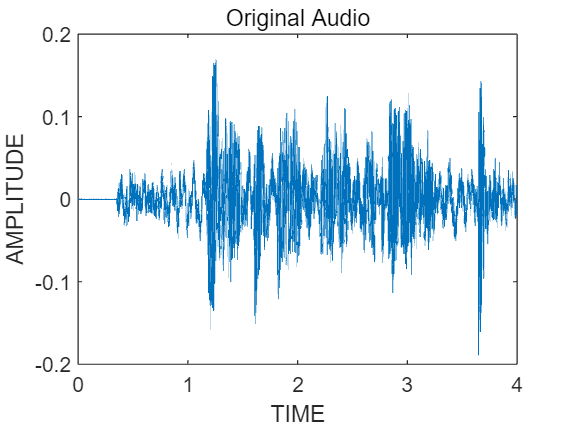

figure(1);
plot(time,audio_data);
xlabel("TIME");
ylabel("AMPLITUDE");
title("Original Audio");
hold on

% plot(time,noise_data);
% hold off

## Power

% Calculate the power for every 0.1s of the signal:
data_period = 0.1;

% Total No. of the period:
period_number = len_time / data_period;

% Step_number indicates the no. of value per period:
step_number = data_range / period_number;

% loop throught each period:
for i = 1:period_number
    % range_left denotes the beginning value in a period:
    range_left = (i-1)*step_number+1;
    
    % range_right denotes the ending value in a period:
    range_right = i*step_number;
    
    % Calculate total power per period(Normalized):
    power_to_test = pow(range_left,range_right,audio_data)/0.1
    
    % Assume power in silence = 10
    % if power_to_test <10, delete that data:
    if power_to_test <10
        for e = range_left:range_right
            audio_data(e) = 0;
        end
    end
end

power_to_test = 9.4064e-06

power_to_test = 9.5554e-06

power_to_test = 9.3598e-06

power_to_test = 2.7680

power_to_test = 9.2716

power_to_test = 4.1414

power_to_test = 3.9703

power_to_test = 6.9526

power_to_test = 9.5247

power_to_test = 18.1196

power_to_test = 13.1152

power_to_test = 46.6185

power_to_test = 106.0041

power_to_test = 51.1220

power_to_test = 52.8341

power_to_test = 15.9841

power_to_test = 95.8084

power_to_test = 19.9541

power_to_test = 83.8433

power_to_test = 56.2997

power_to_test = 21.3455

power_to_test = 10.0057

power_to_test = 55.4171

power_to_test = 46.2032

power_to_test = 44.0079

power_to_test = 12.5131

power_to_test = 43.3073

power_to_test = 17.9935

power_to_test = 89.3095

power_to_test = 85.4998

power_to_test = 61.6567

power_to_test = 24.0514

power_to_test = 10.7548

power_to_test = 11.6194

power_to_test = 18.5036

power_to_test = 11.3360

power_to_test = 108.6911

power_to_test = 13.8741

power_to_test = 9.9358

power_to_test = 7.8608

## Audio player (Filtered)

sound(audio_data, Fs, 8);

## Plot for amplitude vs time (Filtered)

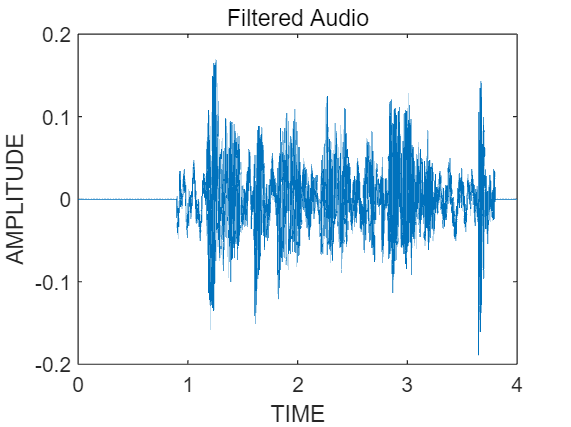

figure(2)
plot(time,audio_data);
xlabel("TIME");
ylabel("AMPLITUDE");
title("Filtered Audio");
hold on

## Parameters after Filtering

length(audio_data)

ans = 177200

new_length = length(audio_data)/2;
audio_data_half = audio_data(1:new_length);

% The below function is used to calaculate the power

function [pow] = pow(timeLeft,timeRight,amp)
    pow=0;
    for i = timeLeft:timeRight
        pow = pow + amp(i)^2;
    end
end
